clear all; close all; clc;

sample_count = 40

sample_count = 40

width = 424;
height = 240;

wo_path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/all_cases_covered/sup_data/beforeCSV_file_for_cloud_";
wo_path_postfix = ".csv";

wo_glare_tensor = zeros(height,width,sample_count);

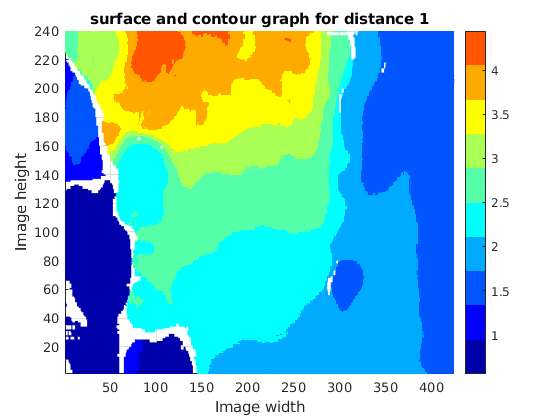

for callback_count = 1:sample_count
    
    h = string(callback_count);
    wo_path = wo_path_pefix+h+wo_path_postfix;
    data = csvread(wo_path);
    
    individual_callbacks = zeros(height,width);
    dist_val = data(:,4);
    
    i=1;
    for x_val = 1:height
        for y_val = 1:width
            individual_callbacks(x_val,y_val) = dist_val(i);
            i = i+ 1;
        end
    end
    
    individual_callbacks = flipud(individual_callbacks);
    wo_glare_tensor(:,:,callback_count) = individual_callbacks;
    
    if(callback_count<=1)
        z_label = "distance";
        save_ = h;
        title_ = "surface and contour graph for "+z_label+" "+save_;
        
        plotter(width,height,individual_callbacks,title_,z_label,save_,0)
        
    end
end

% filtering

width_f = 79;
height_f = 118;
wo_glare_tensor_f = wo_glare_tensor(74:191,205:283,:);
mat2g = wo_glare_tensor_f(:,:,2);
size(mat2g);
max(mat2g, [], 'all')

ans = 3.6175

min(mat2g, [], 'all')

ans = 2.2792

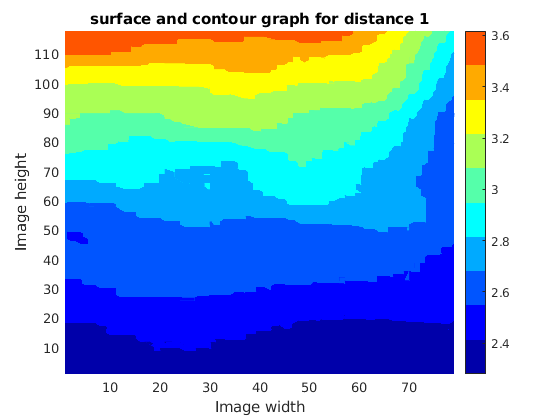

plotter(width_f,height_f,mat2g,title_,z_label,save_,0)

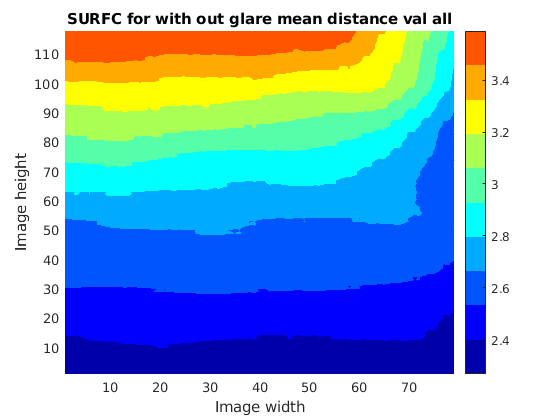

wo_mean_map = nanmean(wo_glare_tensor_f,3);
z_label = "mean distance val";
save_ = "all";
title_ = "SURFC for with out glare "+z_label+" "+save_;
plotter(width_f,height_f,wo_mean_map,title_,z_label,save_,0)

size(wo_mean_map)

ans =    118    79


wo_mean_map = reshape(wo_mean_map,[],1);
size(wo_mean_map)

ans =         9322           1


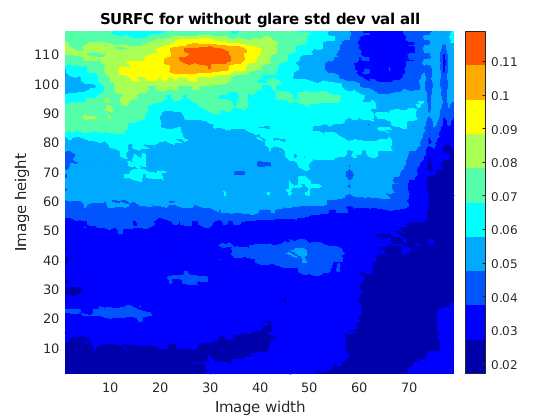

wo_stddev_map = nanstd(wo_glare_tensor_f,[],3);
z_label = "std dev val";
save_ = "all";
title_ = "SURFC for without glare "+z_label+" "+save_;
% z_lim = 0.25;
plotter(width_f,height_f,wo_stddev_map,title_,z_label,save_,0)

size(wo_stddev_map)

ans =    118    79


wo_stddev_map = reshape(wo_stddev_map,[],1);
size(wo_stddev_map)

ans =         9322           1


p = polyfit(wo_mean_map,wo_stddev_map,2)

p =    -0.0039    0.0700   -0.1193


syms x_sym
f = p*[x_sym*x_sym; x_sym; 1]

$$f = -\frac{4500146994995913\,{x_{\mathrm{sym}}}^{2}}{1152921504606846976}+\frac{630190683699973\,x_{\mathrm{sym}}}{9007199254740992}-\frac{2149622569859443}{18014398509481984}$$

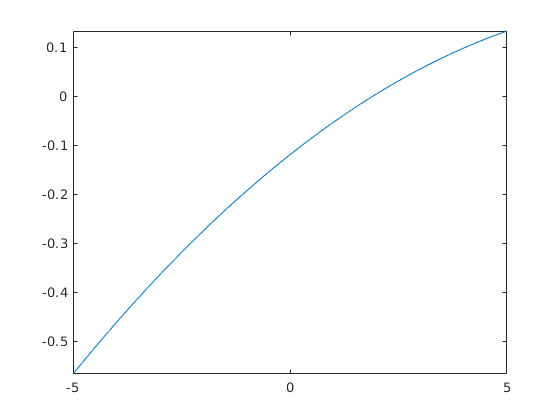

fplot(f)

function plotter(width,height,individual_callbacks,title_,z_label,save_,z_lim)
figure
if(z_lim == 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end
if(z_lim ~= 0)
    x = 1:width;
    y = 1:height;
    z = individual_callbacks;
    [X1,X2]=meshgrid(x,y);
    surfc(X1,X2,z)
    zlim([0,z_lim]);
    grid on
    view(2)
    title(title_)
    xlabel('Image width')
    ylabel('Image height')
    zlabel(z_label)
    shading interp
    colormap (jet(10))
    colorbar
end
end